# **Laborator 7 - Metode de interpolare bazate pe diferențe divizate**

## **PROBLEME**

#### **P1. Implementați o rutină pentru calculul valorilor polinomului de interpolare Hermite cu noduri duble, dându-se punctele în care se face evaluarea, nodurile, valorile funcției și ale derivatei în noduri.**

#### P2. Reprezentați pe același grafic *f* și polinomul său de interpolare Hermite.

point = [0 pi / 4 pi / 2 3 * pi / 2];
nodevals = sin(point);

t = -pi : 0.01 : pi;
hermite_results = Hermite_multiplePoints(point, nodevals, nodevals, t);

fprintf("Reprezentarea grafică a sin(x) și a polinomului său de interpolare Hermite:");

Reprezentarea grafică a sin(x) și a polinomului său de interpolare Hermite:

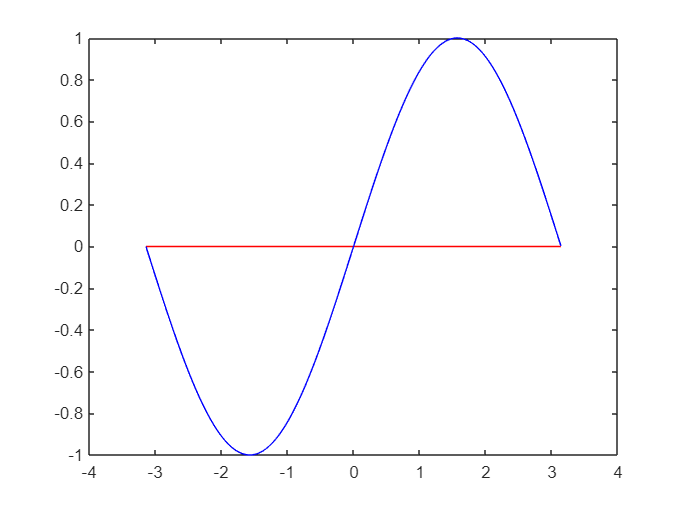

plot(t, hermite_results, 'red');
hold on;
results = sin(t);
plot(t, results, 'blue');
hold off;

#### P3. Scrieți o rutină care reprezintă grafic o cubică parametrică Hermite (o curbă care trece prin 2 puncte date și are în acele puncte tangente date.

% Fie f: [-2, 2] -> R, f(x) = x^2
x = [-2 2];
f = [4 4]; 
fderiv = [-4 4];

t = -2 : 0.01 : 2;
results = Hermite_multiplePoints(x, f, fderiv, t);

fprintf("Reprezentarea grafică a unei cubice parametrice Hermite (x^2):")

Reprezentarea grafică a unei cubice parametrice Hermite (x^2):

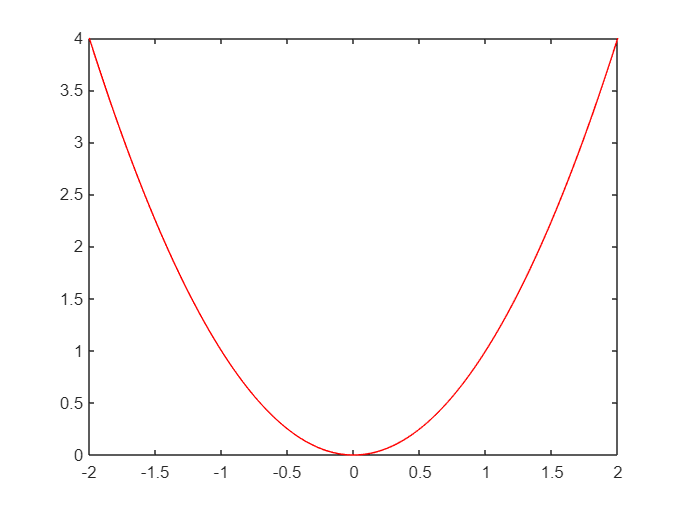

plot(t, results, 'red');

## PROBLEME PRACTICE

#### P1. Pentru f(x) = exp(x) și nodurile de interpolare 0, 1, 2, aproximați f(0.25) prin interpolare Hermite și comparați rezultatul cu cel obținut prin interpolare Lagrange. Dați o delimitare a erorii. Comparați cu rezultatul furnizat de software-ul utilizat.

x = 0.25;
fprintf("Hermite: exp(%f) = %f", x, Hermite([0 1 2], [exp(0) exp(1) exp(2)], [exp(0) exp(1) exp(2)], x));

Hermite: exp(0.250000) = 1.250000

fprintf("Software: exp(%f) = %f", x, exp(x));

Software: exp(0.250000) = 1.284025

#### P2. Utilizați valorile date mai jos pentru a aproxima sin(0.34) utilizând interpolarea Hermite. Dați o delimitare a erorii și comparați-o cu eroarea exactă. Adăugați datele pentru nodul x = 0.33 și refaceți calculele.

x = [0.3, 0.32, 0.35];
f = sin(x);
fderiv = cos(x);
point = [0.34];

h = Hermite(x, f, fderiv, point);
fprintf("PRIMA APROXIMARE:");

PRIMA APROXIMARE:

fprintf("Hermite: sin(%f) = %f", point, h);

Hermite: sin(0.340000) = 0.333734

fprintf("Software: sin(%f) = %f", point, sin(point));

Software: sin(0.340000) = 0.333487

fprintf("EROARE: %f", abs(sin(point) - h));

EROARE: 0.000247


% Adăugăm punctul 0.33 la datele noastre:
x = [0.3, 0.32, 0.33, 0.35];
f = sin(x);
fderiv = cos(x);
point = [0.34];

h = Hermite(x, f, fderiv, point);
fprintf("A DOUA APROXIMARE:");

A DOUA APROXIMARE:

fprintf("Hermite: sin(%f) = %f", point, h);

Hermite: sin(0.340000) = 0.333734

fprintf("Software: sin(%f) = %f", point, sin(point));

Software: sin(0.340000) = 0.333487

fprintf("EROARE: %f", abs(sin(point) - h));

EROARE: 0.000247

#### P3. Un automobil care se deplasează pe un drum drept este cronometrat în mai multe puncte. Datele de observație se dau în tabela de mai jos. Utilizați interpolarea Hermite pentru a prevedea poziția și viteza automobilului la momentul *t* = 10.

timpi = [0, 3, 5, 8, 13];
distante = [0, 225, 383, 623, 993];
viteze = [75, 77, 80, 74, 72];
noduri = [10];

[d, dH] = Hermite_withDerivative(timpi, timpi, viteze, noduri);
fprintf("La momentul t = 10, avem:");

La momentul t = 10, avem:

fprintf("Distanța: %f", d);

Distanța: 2208.362426

fprintf("Viteza: %f", dH);

Viteza: 2136.780893